%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_2D_straight_turn_chemical_reaction');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_2D_straight_turn_chemical_reaction


## Parameters

### Reading the parameters from COMSOL

**Description**: This block reads the parameters from the design in COMSOL. The parameters in COMSOL are defined as global in '`Model Builder/Global Definitions/Parameters`'. The counterpart variables in Matlab follow the same names as the parameters defined in COMSOL. The parameters are first exported in COMSOL to the csv file 'parameters_2D.csv', which comprises a table where the first column refers to the parameters name, and the second column to their value. This code calls the function getVarTable  to read the value of the parameter and their units from this table. Units in this code follows the CSG units, as such units in COMSOL must be converted to CSG. For instance, the units of milimeters must be converted to meters with the factor $10^{-3}$, and similarly with the other units.

% Specify the MAT file for the parameters
csvFileName = 'parameters_2D.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);

%define and initialize to zero the parameters of interest
%geometric parameters
radius_cylinder_1=0;
width_cylinder_in_1=0;
width_cylinder_out_1=0;
angle_turn_1_rad=0;
r_in_1=0;
r_out_1=0;
L=0;%total widht of the rectangle pipe
%flow parameters
p0=0;%this is derived from COMSOL parameters if the Inlet  specify the pressure level within the Laminar Flow(spf), otherwise it must be recalculated.
v0=0;%this is derived from COMSOL parameters if the Inlet  specify the velocity level within the Laminar Flow(spf), otherwise it must be recalculated.
%Sodium parameters
c_NaOH_ini=0;%concentration of released particles
D_NaOH=0;
c_CH3COOH_ini=0;%concentration of particles for the chemical reaction
D_CH3COOH=0;
c_Na=0;%concentration of released particles
D_Na=0;%diffusion coefficient of released particles
d_Na=0;%diameter of the released particles
M_Na=0;%molar mass of the released particles
rho_Na=0;%density of released particles
time_delta=0;%sampling time
time_simul=0;%total simulation time
T=293.15;%default model input in Kelvin
L_inner=0;
L_outer=0;
pulse_duration=0;
fontsize=20;

%reading the parameters from the COMSOL file
[var,factor]=getVarTable(width_cylinder_in_1,table);
width_cylinder_in_1=eval(var{1})*factor

width_cylinder_in_1 = 0.0014

[var,factor]=getVarTable(width_cylinder_out_1,table);
width_cylinder_out_1=eval(var{1})*factor

width_cylinder_out_1 = 0.0014

[var,factor]=getVarTable(radius_cylinder_1,table);
radius_cylinder_1=eval(var{1})*factor

radius_cylinder_1 = 2.0000e-05

[var,factor]=getVarTable(angle_turn_1_rad,table);
angle_turn_1_rad=eval(var{1})*factor

angle_turn_1_rad = 1.0472

[var,factor]=getVarTable(r_in_1,table);
r_in_1=eval(var{1})*factor

r_in_1 = 6.0000e-06

[var,factor]=getVarTable(r_out_1,table);
r_out_1=eval(var{1})*factor

r_out_1 = 4.6000e-05

[var,factor]=getVarTable(p0,table);
p0=eval(var{1})*factor

p0 = 799.9320

[var,factor]=getVarTable(v0,table);
v0=eval(var{1})*factor

v0 = 0.0605

[var,factor]=getVarTable(c_Na,table);
c_Na=eval(var{1})*factor

c_Na = 10

[var,factor]=getVarTable(c_CH3COOH_ini,table);
c_CH3COOH_ini=eval(var{1})*factor

c_CH3COOH_ini = 1.0000e-03

[var,factor]=getVarTable(D_CH3COOH,table);
D_CH3COOH=eval(var{1})*factor

D_CH3COOH = 1.2200e-09

[var,factor]=getVarTable(c_NaOH_ini,table);
c_NaOH_ini=eval(var{1})*factor

c_NaOH_ini = 1.0000e-03

[var,factor]=getVarTable(D_NaOH,table);
D_NaOH=eval(var{1})*factor

D_NaOH = 5.3000e-09

[var,factor]=getVarTable(D_Na,table);
D_Na=eval(var{1})*factor

D_Na = 1.3300e-09

[var,factor]=getVarTable(M_Na,table);
M_Na=eval(var{1})*factor

M_Na = 0.0230

[var,factor]=getVarTable(rho_Na,table);
rho_Na=eval(var{1})*factor

rho_Na = 0.2299

[var,factor]=getVarTable(time_delta,table);
time_delta=eval(var{1})*factor

time_delta = 1.0000e-03

[var,factor]=getVarTable(time_simul,table);
time_simul=eval(var{1})*factor

time_simul = 0.2000

[var,factor]=getVarTable(L_inner,table);
L_inner=eval(var{1})*factor

L_inner = 0.0028

[var,factor]=getVarTable(L_outer,table);
L_outer=eval(var{1})*factor

L_outer = 0.0028

[var,factor]=getVarTable(pulse_duration,table);
pulse_duration=eval(var{1})*factor

pulse_duration = 1.0000e-03

### Evaluating the water viscosity 

**Description: **This evaluates the water viscosity as follows from the analytic function in COMSOL; which is a function of the temperature. The water viscosity is found in COMSOL in '`Component 1/Geometry/Water/rho`'. In this simulation water is the fluid medium where the particles moves.

%Evaluating the water viscosity as follows from the COMSOL definition
% Specify the MAT file for the density
csvFileName = 'viscosity_H2O.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_viscosity=readtable(csvFileName,opts);
str=table_viscosity{1,3};
mu_Water=eval(str{1})

mu_Water = 9.9792e-04

### Evaluating the water density 

**Description: **This evaluates the water density as follows from the analytic function in COMSOL, which is a function of the temperature. The water density is found in COMSOL in '`Component 1/Geometry/Water/rho`'. In this simulation water is the fluid medium where the particles moves.

%Evaluating the water density as follows from the COMSOL definition
% Specify the MAT file for the viscosity
csvFileName = 'density_H2O.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_density=readtable(csvFileName,opts);

%looking for the temperature range
T1=table_density{1,1};
T2=table_density{1,2};
T3=table_density{2,1};
T4=table_density{2,2};

if(T>=T1 && T<=T2)
    str=table_density{1,3};
    rho_Water=eval(str{1})
elseif(T>=T3 && T<=T4)
    str=table_density{2,3};
    rho_Water=eval(str{1})
else
    error('The temperature of your system is not in the range of COMSOL')
end

rho_Water = 998.0585

## Laminar Flow

### Evaluating the flow velocity

**Description**: This section evaluates the profile velocity from theoretical formulations, which follows the Poiseuile flow. This block also contrasts results with the numerical simulation in COMSOL. The theoretcial velocity profile of the fluid within the pipe yields [2, Eq. 4.9 pag. 54]

$v(r)=\frac{\Delta p}{2\mu L}(2ry-y^2)$,

where $\Delta p$ is the inlet pressure, $\mu$ is the viscosity of the medium (water), $L$ is the length(width) of the pipe, $a$ is the radius of the pipe, and $r$ is the radial-axis coordinates. The case $r=0$ denotes the center in the cross-sectional area of the pipe.

When the inlet speed is given, it specifies the average velocity at the center of the pipe, here denoted as $\bar{v}$, and defined as $\bar{v}=\int_0^{a}{v(r)dr}=\frac{2}{3}v_\mathrm{m}$. In such a case, the resulting preasure is 

$\Delta p=\frac{3\mu L\bar{v}}{a^2}$,

and the velocity profile can be alternatively evaluated as


$$v(r)=\frac{3\bar{v}}{2a^2}(a^2-r^2)$$


#### Numerical evaluation in COMSOL

%reading the velocity profile in COMSOL
% Specify the MAT file for the velocity
csvFileName = 'velocity_vs_r.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_velocity=readtable(csvFileName,opts);
%extracting the y-axis, this axis is shifted to the left to match the
%theoretical formulation
y_axis=table_velocity.Var2;
%the values are ordered, as COMSOL returns those unsorted
[y_axis,idx]=sort(y_axis);
v_center_COMSOL=max(table_velocity.Var3);

#### Theoretical evaluation given the inlet pressure

syms y v
%Given the Inlet velocity in COMSOL we evaluate the average pressure as [2, pag. 54]
p0_theo=8*mu_Water*L_inner*v_center_COMSOL/((2*radius_cylinder_1)^2)

p0_theo = 788.2448

p0_COMSOL=p0

p0_COMSOL = 799.9320

%Evaluating the velocity profile [2, Eq. 4.9 pag. 54]
v(y)=p0_theo/(2*mu_Water*L_inner)*(2*radius_cylinder_1*y-y^2);
% v(y)=4*v_center_COMSOL/((2*radius_cylinder_1)^2)*(2*radius_cylinder_1*y-y^2);

v_center=double(v(radius_cylinder_1))

v_center = 0.0563

%theoretical calculation of the maximum speed
p0_theo/(2*mu_Water*L_inner)*(radius_cylinder_1^2)

ans = 0.0563

v_center_COMSOL

v_center_COMSOL = 0.0563




%[1, Eq. (2.33a) pp.28]
v_mean=double(int(v(y),y,0,2*radius_cylinder_1)/(2*radius_cylinder_1))

v_mean = 0.0375

%theoretical calculation of the mean velocity
radius_cylinder_1^2*p0_theo/(3*mu_Water*L_inner)

ans = 0.0375

## Transport of Diluted Species

## Channel Impulse Response

### Evaluating the concentration level

**Description**: This section evaluates the concentration level observed at the ouptup of the rectangular pipes (straigth and turning). The evaluation is performed theoretical and following the simulations provided by COMSOL. Following COMSOL simulation we have the following files

- `CH3COOH_versus_L.csv`: This file stores the average concentration for the outlet line, which is placed at `L_inner `in the $x$ axis. The first column is time, and the concentration values are stored in the second column.

#### Theoretical evaluation of concentration in the straight channel

**Description:** Regarding the theoretical calculation we follow the Taylor's model, see [1, Sec. 4.5]. Whenever the Péclet number fulfill the condition in the above Eq. (1), the particles difussion is homogeneous along the $x$-axis and can be evaluated with the non-convection condition, i.e., free difussion in moved coordinate system. For the free difussion scenario, we regard to the case where there the diffusing substance concentrated initially on the negative side of $x'$, where $x'$ refers to the moving coordinates. The moving coordinates is along the $x$ axis of the unmoved coordinates and moves at the average speed of the velocity profile. Considering the initial conditions [3, Sec. 2.2.3 pp. 13]

$C=C_0$, $x'<0$, $C=0$, $x'>0$, $t=0$,

the solution to the diffusion equation yields [3, Eq. (2.14)]

$C(x',t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x'}{2\sqrt{Dt}}$.             (2)

Then, within the moved coordinate system $x'=x-v_0t$ and $D=D_\mathrm{eff}$, yielding

$C(x,t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x-v_0t}{2\sqrt{D_\mathrm{eff}\,t}}$,          (3)

where [1, Eq. (4.54) pp. 77]

$D_\mathrm{eff}=\frac{a^2v_0^2}{48D}$,                                   (4)

is the effective diffusion coefficient, and $v_0$ is the characteristic speed, here given as the average speed within the microfluidic pipe.

#### Theoretical formulation for the turning pipe

The turning channel introduces the racetrack effect, as such, the turn is also similar to introducing an additional space-shift in the $x$-coordinate on the straight pipe. As the concentration solution en Eq. (9) is valid regardless $y$,  each lamina after the turn will be delayed in the amount $l-l_\mathrm{in}=\phi r_l - \phi r_\mathrm{in}=\phi \Delta r_l$, where $l$ refers to the length of the arcus on a given lamina, $\phi$ is the angle of the turn and $r_l$ is the radius of the arc. As such, Eq.(9) after a turn becomes

$C(x,t)=\frac{1}{2 r}\int_{r_\Delta=0}^{r_\Delta=2r}\frac{1}{2}C_0\, \mathrm{erfc}\left(\frac{x-v_0t-\phi r_\Delta}{2\sqrt{D_\mathrm{eff}\,t}}\right)dr_\Delta$ (11)

which is evaluated after using the primitive of this integral as

$\int{\mathrm{erfc}(x)dx}=x\cdot\mathrm{erfc}(x)-\frac{e^{-x^2}}{\sqrt{\pi}}$ (12)

### Evaluating the channel impulse response

**Description:** This block evaluates the channel impulse response $h(t)$ for the turning channel. The $h(t)$ sequence is evaluated using the above formulation for the observed concentration of molecules. The above formulation is the step response of the channel when $C_0=1$, as such, the channel impulse response can be evaluated as [4, Eq. (7b), pp. 78]

$h(t)=\frac{\partial}{\partial t}C(x,t)\bigg|_{C_0=1}$,  (7)

where $C(x,t)$ is given as in Eq. (3) above.

## Synthesis of microfluidic circuit

**Description:** This block develops the coefficients of a pretrained CNN in a microfluidic circuit. Given a set of coefficients, they are first sorted, and the largest coefficient is implemented with shortest pipe (1), while the second largest coefficient with the pipe 2 and so on.

The first coefficient is synthesized in the pipe 1 (straight channel) in two steps. First we find the value of $\tau$ that fullfils the condition

$\frac{\partial^2}{\partial \tau^2}{c}(x,\tau)\bigg|_{C_0=1}=0$ (16)

where ${c}(x,\tau)$ is given in Eq. (9)

%we take the value for the length of the pipe 1, this requires running the
%Master file first or loading the calculations for the pipe 1 with the file
load dataset\tau_data.mat
idx=30;
L_1=l_vector(idx);
tau_1=tau(idx);

%defining the length interval
total_points=100;
l_ini=270e-6;
l_end=2e-2;
l_vector=linspace(l_ini,l_end,total_points);

%defining the time interval
total_points=1e4/2;
time_ini=1e-6;
time_end=4.5;
time_vector = linspace(time_ini,time_end , total_points);

syms t l rd r varphi C_0

%spatial-restriction
%L_1 refers to the solution for the straight pipe, evaluated in the Master
%file
l=L_1/sin((pi-varphi)/2);
%Evaluating the mean velocity [2, pag. 54] with the length l
v_char=r^2*p0/(3*mu_Water*l)

$$v\_char = -\frac{13291150114052741822554411780093771776\,r^{2}\,\sin\left(\frac{\phi }{2}-\frac{\pi }{2}\right)}{300915161960464821779778683455}$$

%Evaluating the effective diffusion coeff [1, Eq.(4.54) pp.77]
D_eff=r^2*v_char^2/48/D_NaOH;

%Evaluating the concentration of the turning channel
% Define the substitution for x
z = (l - v_char*t + varphi*rd) / (2*sqrt(D_eff*t));

% Define the integrand
integrand = 1/2*C_0*erfc(z);

%Performing the integral
c_avg=1/(2*r)*int(integrand,rd);

%Evaluating the integral limits
c_avg_int=subs(c_avg,rd,2*r)-subs(c_avg,rd,0)

%Replacing the constants
c=subs(c_avg_int,[C_0],[1]);

%Channel impulse response (CIR)
h_turning=diff(c,t);
%Derivative of the CIR
h_diff=diff(h_turning,t);

% %% for validation purposes only
% h_value_1=subs(h,[varphi,r],[pi/3,radius_cylinder_1]);
% h_value_2=subs(h,[varphi,r],[pi/3,radius_cylinder_1/2.5]);
% h_value_3=subs(h,[varphi,r],[pi/3,radius_cylinder_1*2]);
% figure;
% dec_factor=20;
% plot(time_vector(1:dec_factor:end)*10^3,subs(h_value_1(1:dec_factor:end),t,time_vector(1:dec_factor:end))*pulse_duration,'LineWidth',2); grid on; hold on;
% plot(time_vector(1:dec_factor:end)*10^3,subs(h_value_2(1:dec_factor:end),t,time_vector(1:dec_factor:end))*pulse_duration,'LineWidth',2);
% plot(time_vector(1:dec_factor:end)*10^3,subs(h_value_3(1:dec_factor:end),t,time_vector(1:dec_factor:end))*pulse_duration,'LineWidth',2);
% xlabel('Time [ms]','Interpreter','latex');
% ylabel('$h(t)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);


total_points=100;

varphi_ini=pi/1000;
varphi_end=pi/2-pi/100;
varphi_vector=linspace(varphi_ini,varphi_end,total_points);

r_ini=1e-9

r_ini = 1.0000e-09

r_end=radius_cylinder_1;
r_vector=linspace(r_ini,r_end,total_points);

r_sol=zeros(1,total_points);

%delay restriction
k_tau=5;
%looking for the pairs (t,l) as a solution to Eq. (16)
for i_varphi=1:total_points
    i_varphi/total_points*100
    obj_fcn_time=subs(h_diff,t,k_tau*tau_1);
    obj_fcn=subs(obj_fcn_time,varphi,varphi_vector(i_varphi));

    % figure;
    % fplot(obj_fcn,[1e-9 radius_cylinder_1]); grid on;

    [max_value, max_r] = max(subs(obj_fcn,r,r_vector));
    [min_value, min_r] = min(subs(obj_fcn,r,r_vector));
    r_sol(i_varphi)=vpasolve(obj_fcn,r,[r_vector(max_r) r_vector(min_r)]);
end

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7.0000

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14.0000

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 20

ans = 21

ans = 22

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28.0000

ans = 29.0000

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 35

ans = 36

ans = 37

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 44

ans = 45

ans = 46

ans = 47

ans = 48

ans = 49

ans = 50

ans = 51

ans = 52

ans = 53

ans = 54

ans = 55.0000

ans = 56.0000

ans = 57.0000

ans = 58.0000

ans = 59

ans = 60

ans = 61

ans = 62

ans = 63

ans = 64

ans = 65

ans = 66

ans = 67

ans = 68

ans = 69

ans = 70

ans = 71

ans = 72

ans = 73

ans = 74

ans = 75

ans = 76

ans = 77

ans = 78

ans = 79

ans = 80

ans = 81

ans = 82

ans = 83

ans = 84

ans = 85

ans = 86

ans = 87

ans = 88

ans = 89

ans = 90

ans = 91

ans = 92

ans = 93

ans = 94

ans = 95

ans = 96

ans = 97

ans = 98

ans = 99

ans = 100


%Saving results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Save the results into the specified folder
save(fullfile(outputFolder, strcat('radius_data_turning_pipe_tau_',num2str(k_tau),'.mat')) ,'r_sol', 'varphi_vector');


## For validation purposes only

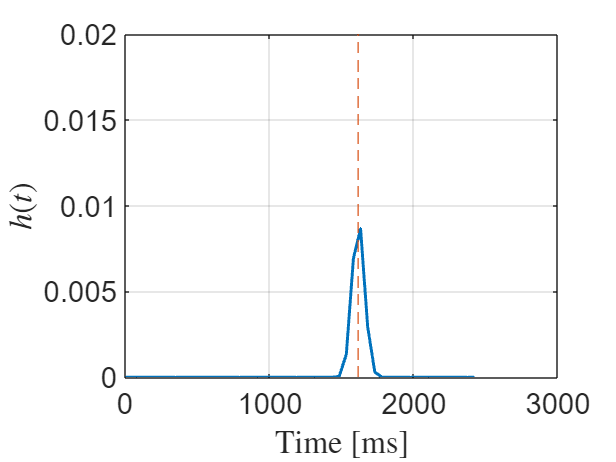

% figure;
% fplot(obj_fcn,[r_vector(max_r) r_vector(min_r)]); grid on;

% i_varphi=1;
% h_value_1=subs(h,[varphi,r],[varphi_vector(i_varphi),radius_cylinder_1]);
% h_value_2=subs(h,[varphi,r],[varphi_vector(i_varphi),radius_cylinder_1/2.5]);
% h_value_3=subs(h,[varphi,r],[varphi_vector(i_varphi),radius_cylinder_1*2]);
% figure;
% dec_factor=20;
% plot(time_vector(1:dec_factor:end)*10^3,subs(h_value_1(1:dec_factor:end),t,time_vector(1:dec_factor:end))*pulse_duration,'LineWidth',2); grid on; hold on;
% plot(time_vector(1:dec_factor:end)*10^3,subs(h_value_2(1:dec_factor:end),t,time_vector(1:dec_factor:end))*pulse_duration,'LineWidth',2);
% plot(time_vector(1:dec_factor:end)*10^3,subs(h_value_3(1:dec_factor:end),t,time_vector(1:dec_factor:end))*pulse_duration,'LineWidth',2);
% xlabel('Time [ms]','Interpreter','latex');
% ylabel('$h(t)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);

%h(t) vs time
figure;
i_varphi=90;
w_i=subs(h_turning,[r,varphi],[r_sol(i_varphi),varphi_vector(i_varphi)])*pulse_duration;
time_vector=linspace(1e-3,1.5*k_tau*tau_1,50);
plot(time_vector*10^3,subs(w_i,t,time_vector),'LineWidth',2); grid on; hold on;
% i_varphi=100;
% fplot(subs(h_turning,[r,varphi],[r_sol(i_varphi),varphi_vector(i_varphi)])*pulse_duration,[1e-3,2],'LineWidth',2);
plot([k_tau*tau_1 k_tau*tau_1]*1e3,[0 2e-2],'--');
xlabel('Time [ms]','Interpreter','latex');
ylabel('$h(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 1 0 5e-2])

% figure;
% % fplot(subs(h,[l],[l_vector(1)]),[0 0.5e-3]); grid on;
% % fplot(subs(h_diff,[l],[l_vector(1)]),[0 0.5e-3]); grid on;
% % fplot(obj_fcn,[0 0.5e-3]); grid on;
% 
% figure;
% i_varphi=1;
% h_l=subs(h_turning,l,l_vector(i))
% plot(time_vector, double(subs(h_l,[t],[time_vector]))); hold on; grid on;
% plot(tau(i),h_peak(i),'o')

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e-3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] J. Crank. 1986. The Mathematics of Diffusion. Oxford University Press.

[4] A. B. Carlson, P. B. Crilly, and J. C. Rutledge, Communication Systems: An Introduction to Signals and Noise in Electrical Communication, 4th ed. New York City, NY: McGraw-Hill, 2002, p. 850.

[5] R. Chang, *Chemistry*. Boston, Mass.: McGraw-Hill Education, 1998.  